# Replicate the contrast sensitivity function (CSF) in Cottaris et al 2019 using ISETBioCSFGenerator (Part 1)

The goal of this live script is to use the ISETBioCSFGenerator to replicate a CSF shown in Cottaris et al 2019 (**Figure 7A**). This script can generally be divided into the following sections:

- Create sinusoidal gratings windowed by a half-cosine envelope

- Define the optics and cone mosaics of the observer

- Specify parameters for threshold estimation

- Specify inference engine (Poisson-noise ideal observer). See Part 2 for other inference engines (SVM-PCA, SVM template-linear and SVM template energy)

- Simulate and visualize the CSF

## 1. Create sinusoidal gratings windowed by a half-cosine envelope

clear all; close all; clc; 

% Generate a display for presenting stimuli and place it at a viewing 
% distance of 57 cm
presentationDisplay = displayCreate('LCD-apple', 'viewing distance', 0.57);
% get the sampled wavelength
wave                = displayGet(presentationDisplay, 'wave');
% get gamma table
gamma_func          = displayGet(presentationDisplay,'gamma');
% define an exponential function, and fit for the expoenent a
ft                  = fittype('x^a');
RGB_max             = size(gamma_func,1);
rgb_intend          = (1:RGB_max)'./RGB_max;
expCurveFit_struct  = fit(repmat(rgb_intend,[3,1]), gamma_func(:),ft);

% extract the best-fitting exponent a
gammaTableExponent  = expCurveFit_struct.a; %2.0371

% compute the xyY coordinates for the display background and define chromatic direction
rgb2xyz             = displayGet(presentationDisplay, 'rgb2xyz')';
% rgb values for a gray background
rgb_background      = [0.5;0.5;0.5];
% Convert CIE RGB values to CIE XYZ values
XYZ_gray            = rgb2xyz*rgb_background;
% Convert to Chromaticity Coordinates
x                   = XYZ_gray(1)/sum(XYZ_gray); %0.3124
y                   = XYZ_gray(2)/sum(XYZ_gray); %0.3396
% Make the mean luminance = 34 cd/m2
Y                   = 34;                        

% define chromatic direction for achromatic stimuli
chromaDir           = [1.0, 1.0, 1.0]'; 

The stimuli are sinusoidal gratings windowed using a half-cosine spatial modulation which spans 7.5 cycles of the grating. The number of cycles is fixed while the size of the stimuli is varied as a function of spatial frequency. Seven levels of spatial frequencies are selected. The windowing makes the spatial extent of each stimulus inversely proportional to its spatial frequency. More details regarding the stimulus' parameters are shown in the table below.

Visualize the half-cosine envelope and an example of the windowed sinusoidal grating: 

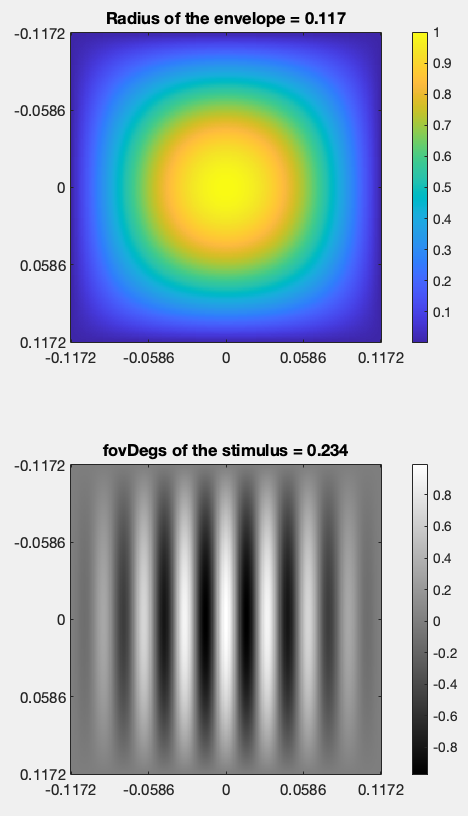

% define spatial frequency
freq           = sort([50, 2.^(6:-1:1)]); 
% we test 7 levels
numFreq        = length(freq);
% the number of cycles is fixed
cyc_fixed      = 7.5;
% the size of the stimulus increases with decreasing spatial frequency
S_width        = cyc_fixed ./ freq; 
% the radius of the envelope is half of the stimulus size
% (i.e., the diameter of the envelope = the stimulus size)
G_width        = S_width ./ 2;

% 
sceneComputeFunction = @sceGrating;
% initialize a cell that stores all the scene engines
theSceneEngine       = cell(1,numFreq);
for f = 1:numFreq
    gratingParams   = struct(...
        'screenDisplay', presentationDisplay.name,...           % display: screen display type
        'viewingDistanceMeters', presentationDisplay.dist, ...  % display: viewing distance
        'bitDepth', 20, ...                                     % display: length of LUT
        'gammaTableExponent', gammaTableExponent, ...           % display: shape of LUT, 1 = Linear
        'spectralSupport', wave, ...                            % display: spectral support of the primary SPDs, in nanometers
        'meanLuminanceCdPerM2', Y, ...                          % background: mean luminance, in candellas per meter squared
        'meanChromaticityXY', [x,y], ...                        % background: neutral mean chromaticity
        'coneContrastModulation', chromaDir, ...                % chromatic direction: LMS cone contrasts
        'warningInsteadOfErrorOnOutOfGamut', false, ...         % chromatic: whether to throw an error or a warning if out-of-gamut pixels are generated
        'fovDegs', S_width(f), ...                              % spatial: field of view, in degrees
        'minPixelsNumPerCycle', 10, ...                         % spatial: min number of pixels per grating spatial period (to minimize aliasing effects)
        'pixelsNum', 256, ...                                   % spatial: desired size of stimulus in pixels - this could be larger depending on the minPixelsNumPerCycle, the SF, and the FOV
        'spatialFrequencyCyclesPerDeg', freq(f), ...            % spatial: grating spatial freequency, in cycles/deg
        'orientationDegs', 90, ...                              % spatial: grating orientation, in degrees
        'spatialPhaseDegs', 0, ...                              % spatial: grating spatial phase, in degrees
        'spatialPositionDegs', [0.0 0.0], ...                   % spatial: center of grating, in degrees
        'spatialModulation', 'harmonic', ...                    % spatial: contrast modulation - choose between {'harmonic', 'square'} for sinusoidal/square spatial modulation 
        'spatialModulationDomain', 'cartesian', ...             % spatial: domain of spatial modulation - choose between {'cartesian', 'polar'}
        'spatialEnvelope', 'halfcos', ...                       % spatial: envelope - choose between {'disk', 'rect', 'soft'}
        'spatialEnvelopeRadiusDegs', G_width(f),...             % spatial: radius of the spatial envelope, in degs    
        'temporalModulation', 'flashed', ...                    % temporal modulation mode: choose between {'flashed', 'drifted', 'counter phase modulated'}
        'temporalModulationParams', struct(...                  % temporal: modulation params struct
            'stimOnFrameIndices', 1, ...                        %   frame indices that correspond to 'stimulus on'
            'stimDurationFramesNum', 1), ...                    %   the total number of frames for the stimulus presentation
        'frameDurationSeconds', 100/1000);                      % temporal: frame duration, in seconds
    theSceneEngine{f} = sceneEngine(sceneComputeFunction, gratingParams);
end

## 2. Define the optics and cone mosaics of the observer

In the paper, the optics of Thibos subject #3 is selected as a representative observer. The measured pupil size is 3mm, which is also the pupil size for calculation. More details about the Zernike coefficients (up to order of 5) are shown in the table below:

% Thibos subject number
ThibosSubj      = 54;
% measured pupil size in their study
measuredPupilMM = 3;
% pupil size for calculation
calcPupilMM     = 3;
% which eye
subjEye         = 'left eye';
theNeuralEngine = cell(1, numFreq);

for f = 1:numFreq
    % define cone mosaic 
    % the rest unspecified arguments take the default values
    theCMosaic = cMosaic(...
        'sizeDegs', [S_width(f),S_width(f)],... % [sx, sy]. Width and height of the mosaic, in degrees.
        'eccentricityDegs', [0 0], ...          % [x,y]. Center of the mosaic, in degrees.
        'whichEye', subjEye, ...                % Which eye.
        'integrationTime', 0.1);                % Scalar. Integration time in seconds.

    % define optics given subject #3
    % only do it once because it does not change with spatial frequency
    if f == 1
        [theOptics, ~, ~, ~, ~, zCoeffs] = ...
            ThibosOptics.oiForSubjectAtEccentricity(ThibosSubj, ...
            subjEye, calcPupilMM, wave, theCMosaic.micronsPerDegree, ...
            'measurementPupilDiameterMM', measuredPupilMM,...
            'wavefrontSpatialSamples', length(wave), ...
            'inFocusWavelength', 550,...
            'subtractCentralRefraction', false,...
            'zeroCenterPSF', true,...
            'flipPSFUpsideDown', false);
    end

    % Instantiate a neural response engine using a desired neural compute
    % function
    theNeuralEngine{f} = neuralResponseEngine(...
        @nrePhotopigmentExcitationsCmosaic);

    % Customize the neural pipeline (theCMosaic & theOptics)
    theNeuralEngine{f}.customNeuralPipeline(struct(...
                    'coneMosaic', theCMosaic, ...
                    'optics', theOptics));
end

Loading cone mosaic data from /Users/dhb/Documents/MATLAB/toolboxes/isetbio/isettools/ganglioncells/data/lattices/left_eye_cones_58deg_mosaic.
Loading cone mosaic data from /Users/dhb/Documents/MATLAB/toolboxes/isetbio/isettools/ganglioncells/data/lattices/left_eye_cones_58deg_mosaic.
Loading cone mosaic data from /Users/dhb/Documents/MATLAB/toolboxes/isetbio/isettools/ganglioncells/data/lattices/left_eye_cones_58deg_mosaic.
Loading cone mosaic data from /Users/dhb/Documents/MATLAB/toolboxes/isetbio/isettools/ganglioncells/data/lattices/left_eye_cones_58deg_mosaic.
Loading cone mosaic data from /Users/dhb/Documents/MATLAB/toolboxes/isetbio/isettools/ganglioncells/data/lattices/left_eye_cones_58deg_mosaic.
Loading cone mosaic data from /Users/dhb/Documents/MATLAB/toolboxes/isetbio/isettools/ganglioncells/data/lattices/left_eye_cones_58deg_mosaic.
Loading cone mosaic data from /Users/dhb/Documents/MATLAB/toolboxes/isetbio/isettools/ganglioncells/data/lattices/left_eye_cones_58deg_mosaic.

Visualize the point spread function given the optics of Thibos subject #3

disp('Zernike coefficients of Thibos subject #3:'); disp(zCoeffs);

Zernike coefficients of Thibos subject #3:
   -0.2132
    0.2232
   -0.0162
    0.0366
    0.0182
   -0.0432
   -0.0436
    0.0515
   -0.0131
    0.0055
   -0.0013
    0.0008
    0.0076
   -0.0106
   -0.0022



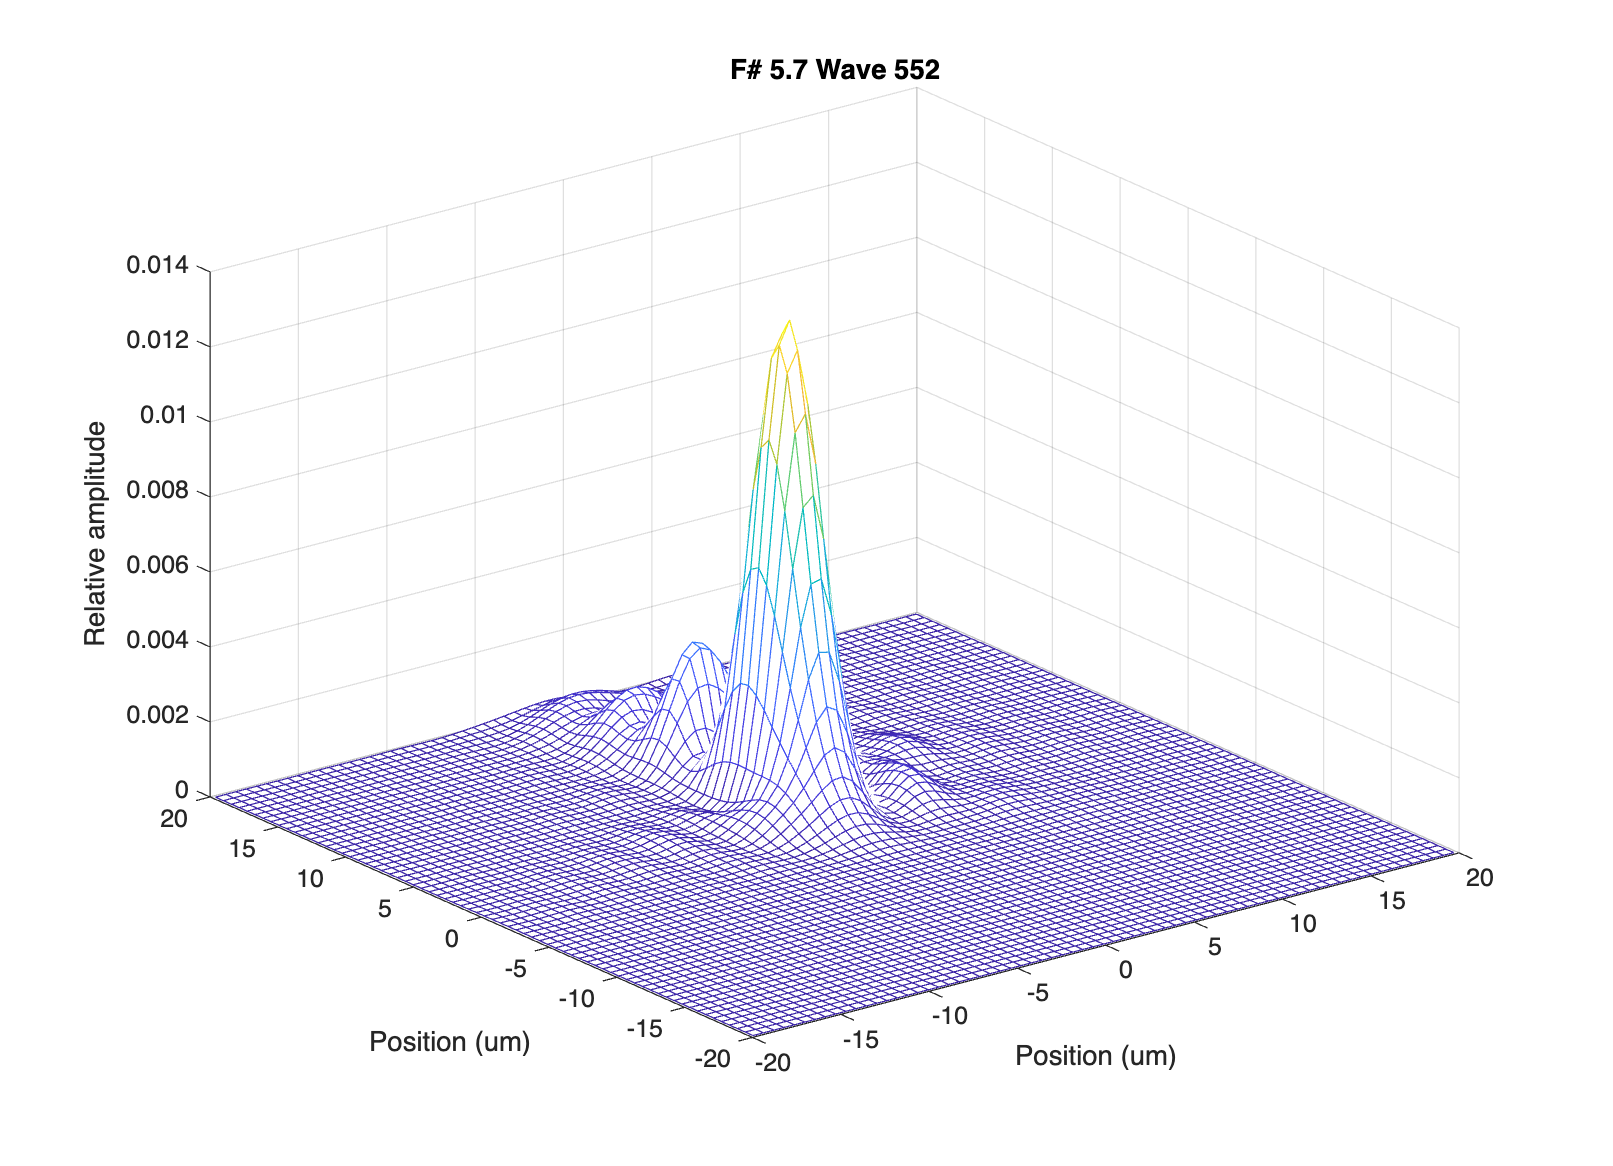


ThiboSubj_wvf = wvfCreate('zcoeffs', zCoeffs, 'measured pupil', 3,...
    'calculated pupil', 3, 'measured wavelength', 550, 'calc wave', wave);
ThiboSubj_wvf = wvfCompute(ThiboSubj_wvf,'humanlca',true);
wvfPlot(ThiboSubj_wvf, 'psf', 'wave',552, 'unit','um','plotrange',20);

## 3. Specify parameters for threshold estimation

The psychometric function is defined as the following:

$\tilde{P} \left(\alpha ,\beta ,s\right)=\gamma +\left(1-\lambda -\gamma \right)\cdot P\left(\alpha ,\beta ,s\right)=\frac{1}{2}+\frac{1}{2}\exp \left(-{10}^{\beta \cdot \frac{\left(s-\alpha \right)}{\log \left(10\right)}} \right),$ where

The final threshold is defined as ${10}^{-\alpha }$, and contrast sensitivity as $\frac{1}{{10}^{-\alpha } }$.

%% Parameters for threshold estimation/quest engine
thresholdPara = struct('logThreshLimitLow', 5.5, ...  %approximately = contrast sensitivity of 3e5
                       'logThreshLimitHigh', 0.0, ... %contrast sensitivity of 1
                       'logThreshLimitDelta', 0.1, ... 
                       'slopeRangeLow', 1/20, ...
                       'slopeRangeHigh', 60/20, ...
                       'slopeDelta', 2/20, ...
                       'thresholdCriterion', 0.7071); %pCorrect = 0.7071

% method of constant stimuli
% specify grids for the threshold and the slope
estDomain  = -thresholdPara.logThreshLimitLow : thresholdPara.logThreshLimitDelta : -thresholdPara.logThreshLimitHigh;
slopeRange = thresholdPara.slopeRangeLow: thresholdPara.slopeDelta : thresholdPara.slopeRangeHigh;

% specify all the free parameters for the quest engine
questEnginePara = struct(...
    'employMethodOfConstantStimuli', true,...   
    'nTest',512,...                             %Number of trials per contrast level when running in validation mode.
    'validation', true,...                      %If set to true run the entire psychometric curve
    'blocked', true, ...                        %Run trials blocked by contrast.  Set this to true if a block of trials at same contrast will be run.
    'estDomain', estDomain, ...                 %the discretized log thresholds we defined
    'slopeRange', slopeRange, ...               %the discretized log slope we defined
    'qpPF', @qpPFWeibullLog, ...                %Psychometric function
    'guessRate', 0.5, ...                       %fixed guess rate (unbiased)
    'lapseRate', 1e-4);                         %fixed lapse rate (almost 0)

## 4. Specify inference engine (Poisson-noise ideal observer)

In this live script, we use ideal stimuli-known Poisson noise observer. In short, this classifier assumes that the observer has complete knowledge of the possible stimuli (i.e., knows the exact intensity distributions, durations, and positions of the stimuli and the process of receptors absorbing photons being a Poisson). 

This classifier is used in a two-interval-forced-choice (2IFC) task, in which the observer is presented with a null stimulus (a uniform gray background) in a randomly selected interval and a test stimulus (a sinusoid grating) in the other interval. The task is to determine which interval contains the test stimulus.

Let $Z_i$ be the number of the quanta absorbed in the $i^{\textrm{th}}$receptor on a given trial, and let $\left.p\left(r_1 ,\ldotp \ldotp \ldotp ,r_n \right|s_{\textrm{test}} \right)$ and $\left.p\left(r_1 ,\ldotp \ldotp \ldotp ,r_n \right|s_{\textrm{null}} \right)$ be the joint probability densities of ${\mathit{\mathbf{R}}}_{\textrm{test}} =\left\lbrack R_{\textrm{test},1} ,\ldotp \ldotp \ldotp ,R_{\textrm{test},n} \right\rbrack \;\textrm{and}\;{\mathit{\mathbf{R}}}_{\textrm{null}} =\left\lbrack R_{\textrm{null},1} ,\ldotp \ldotp \ldotp ,R_{\textrm{null},n} \right\rbrack$, respectively for stimuli $s_{\textrm{test}}$ and $s_{\textrm{null}}$. The observer makes the correct decision if the log probability of correct responses is equal to the log likelihood of $s_{\textrm{test}}$ given the response ${\mathit{\mathbf{R}}}_{\textrm{test}}$ plus the log likelihood of $s_{\textrm{null}}$ given the response ${\mathit{\mathbf{R}}}_{\textrm{null}}$:


$${\log \;p}_{\textrm{correct}} =\log \;\left(L\left(s_{\textrm{test}} |{\mathit{\mathbf{R}}}_{\textrm{test}} \right)\cdot L\left(s_{\textrm{null}} |{\mathit{\mathbf{R}}}_{\textrm{null}} \right)\right),$$


$\left.\left.=\log \left(p\left(R_{\textrm{test},1} ,\ldotp \ldotp \ldotp ,R_{\textrm{test},n} \right|s_{\textrm{test}} \right)\cdot p\left(R_{\textrm{null},1} ,\ldotp \ldotp \ldotp ,R_{\textrm{null},n} \right|s_{\textrm{null}} \right)\right)$.

Analogously, 

$\left.\left.\log \;p_{\textrm{incorrect}} =\log \left(p\left(R_{\textrm{test},1} ,\ldotp \ldotp \ldotp ,R_{\textrm{test},n} \right|s_{\textrm{null}} \right)\cdot p\left(R_{\textrm{null},1} ,\ldotp \ldotp \ldotp ,R_{\textrm{null},n} \right|s_{\textrm{test}} \right)\right)$,

where

$\left.p\left(R_1 ,\ldotp \ldotp \ldotp ,R_n \right|s\right)=\prod_{i=} \frac{{s_i }^{R_i } \cdot \exp \left\lbrack -s_i \right\rbrack }{R_i !}$, 

$i$ indexes cone photoreceptors and ranges from 1 to $n$. Plugging this in ${\log \;p}_{\textrm{correct}}$ and ${\log \;p}_{\textrm{incorrect}}$, we have


$$\left.{\log \;p}_{\textrm{correct}} =\log \left(p\left(R_{\textrm{test},1} ,\ldotp \ldotp \ldotp ,R_{\textrm{test},n} \right|s_{\textrm{test}} \right)\right)+\log \left(\left.p\left(R_{\textrm{null},1} ,\ldotp \ldotp \ldotp ,R_{\textrm{null},n} \right|s_{\textrm{null}} \right)\right)$$



$$=\log \left(\prod_{i=1} \frac{{s_{\textrm{test},\;i} }^{R_{\textrm{test},\;i} } \cdot \exp \left\lbrack -s_{\textrm{test},\;i} \right\rbrack }{R_{\textrm{test},\;i} !}\right)+\log \left(\prod_{i=1} \frac{{s_{\textrm{null},\;i} }^{R_{\textrm{null},\;i} } \cdot \exp \left\lbrack -s_{\textrm{null},\;i} \right\rbrack }{R_{\textrm{null},\;i} !}\right)$$



$$=\sum_{i=1} \;\left(R_{\textrm{test},i} \cdot \log \left(s_{\textrm{test},i} \right)-s_{\textrm{test},i} -\log \left(R_{\textrm{test},i} !\right)\right)+\sum_{i=1} \;\left(R_{\textrm{null},i} \cdot \log \left(s_{\textrm{null},i} \right)-s_{\textrm{null},i} -\log \left(R_{\textrm{null},i} !\right)\right)$$



$$=\sum_{i=1} \;\left(R_{\textrm{test},i} \cdot \log \left(s_{\textrm{test},i} \right)-s_{\textrm{test},i} \right)+\sum_{i=1} \;\left(R_{\textrm{null},i} \cdot \log \left(s_{\textrm{null},i} \right)-s_{\textrm{null},i} \right)+\textrm{const1},$$


where $s_{\textrm{test},i}$ and $s_{\textrm{null},i}$ are the noise-free response of receptor $i$ to the test and null stimulus, respectively. Analogously, 


$${\log \;p}_{\textrm{incorrect}} =\sum_{i=1} \;\left(R_{\textrm{test},i} \cdot \log \left(s_{\textrm{null},i} \right)-s_{\textrm{null},i} \right)+\sum_{i=1} \;\left(R_{\textrm{null},i} \cdot \log \left(s_{\textrm{test},i} \right)-s_{\textrm{test},i} \right)+\textrm{const1}\ldotp$$


The observer makes a correct judgment if $p_{\textrm{correct}} >$$p_{\textrm{incorrect}}$, that is,

$\frac{p_{\textrm{correct}} }{p_{\textrm{incorrect}} }>1\Longrightarrow \log \frac{p_{\textrm{correct}} }{p_{\textrm{incorrect}} }>0\Longrightarrow \log \left(p_{\textrm{correct}} \right)-\log \left(p_{\textrm{incorrect}} \right)>0$.

Note that $\textrm{const1}$ gets canceled out, so we don't even need to calculate that, which is very nice because it's quite computationally exhausting to do so. 

The observer makes a correct judgment if $p_{\textrm{correct}}$ is sufficiently close to $p_{\textrm{incorrect}}$, that is,


$$|\log \left(p_{\textrm{correct}} \right)-\log \left(p_{\textrm{incorrect}} \right)|<\epsilon ,$$


where $\epsilon$ is a very small number (e.g., 1e-10).

% Given that this classifier assumes that the observer has complete knowledge 
% of the possible stimuli, we use the trainFlag value of 'none' to indicate that 
% the classifier should be trained with a noise free version of the stimuli. 
% We'll test with noisy values, however.
%
% Since this is a template type of classifer, we can just pass one noise free 
% examplar of the NULL and TEST stimuli.  We choose here to predict performance 
% on 512 stimuli for each contrast tested.  This is because classification
% of individual stimuli is pretty fast for this classifier, and we might as well
% get a good estimate of performance for each contrast tested.
classifierPara = struct('trainFlag', 'none', ...
                        'testFlag', 'random', ...
                        'nTrain', 1, ...
                        'nTest', 512);

% Ideal signal-known Poisson noise classifier for TAFC
classifierEngine = responseClassifierEngine(@rcePoisson, classifierPara);


## 5. Simulate and visualize the CSFs

% initialize log threshold and contrast sensitivity
[logThreshold, sensitivity] = deal(NaN(1, numFreq));
% initialize questObj for visualizing the psychometric functions later
questObj                    = cell(1, numFreq);
% initialize a matrix to store the best-fitting parameters for the
% psychometric functions
PFparam                     = NaN(numFreq, 4);

%loop through all the tested spatial frequencies
for f = 1:numFreq
    % call computeThresholdTAFC to compute the log threshold
    % this function assumes the task is 2IFC
    % (e.g., One interval has a test stimulus and the other has a null
    % stimulus. The task is to determine which interval contains the test
    % stimulus)
    [logThreshold(f), questObj{f}, ~, PFparam(f,:)] = ...
        computeThreshold(theSceneEngine{f}, theNeuralEngine{f}, ...
        classifierEngine, classifierPara, thresholdPara,...
        questEnginePara,'TAFC',true);
    % if we want to visualize the stimuli, we can set the following two
    % varargin to be true
    % 'visualizeStimulus', true, 'visualizeAllComponents', true
    
    % contrast sensitivity
    sensitivity(f) = 1/(10 .^ logThreshold(f));
end

Testing C = 0.0003%
	Skipping blur by cone aperture.
	Consider increasing the # of pixels in the stimulus or decrease the stimulus FOV.
	Skipping blur by cone aperture.
	Consider increasing the # of pixels in the stimulus or decrease the stimulus FOV.
	Skipping blur by cone aperture.
	Consider increasing the # of pixels in the stimulus or decrease the stimulus FOV.
	Skipping blur by cone aperture.
	Consid

Plot the stimulus with the highest contrast and the psychometric function given each spatial freqency

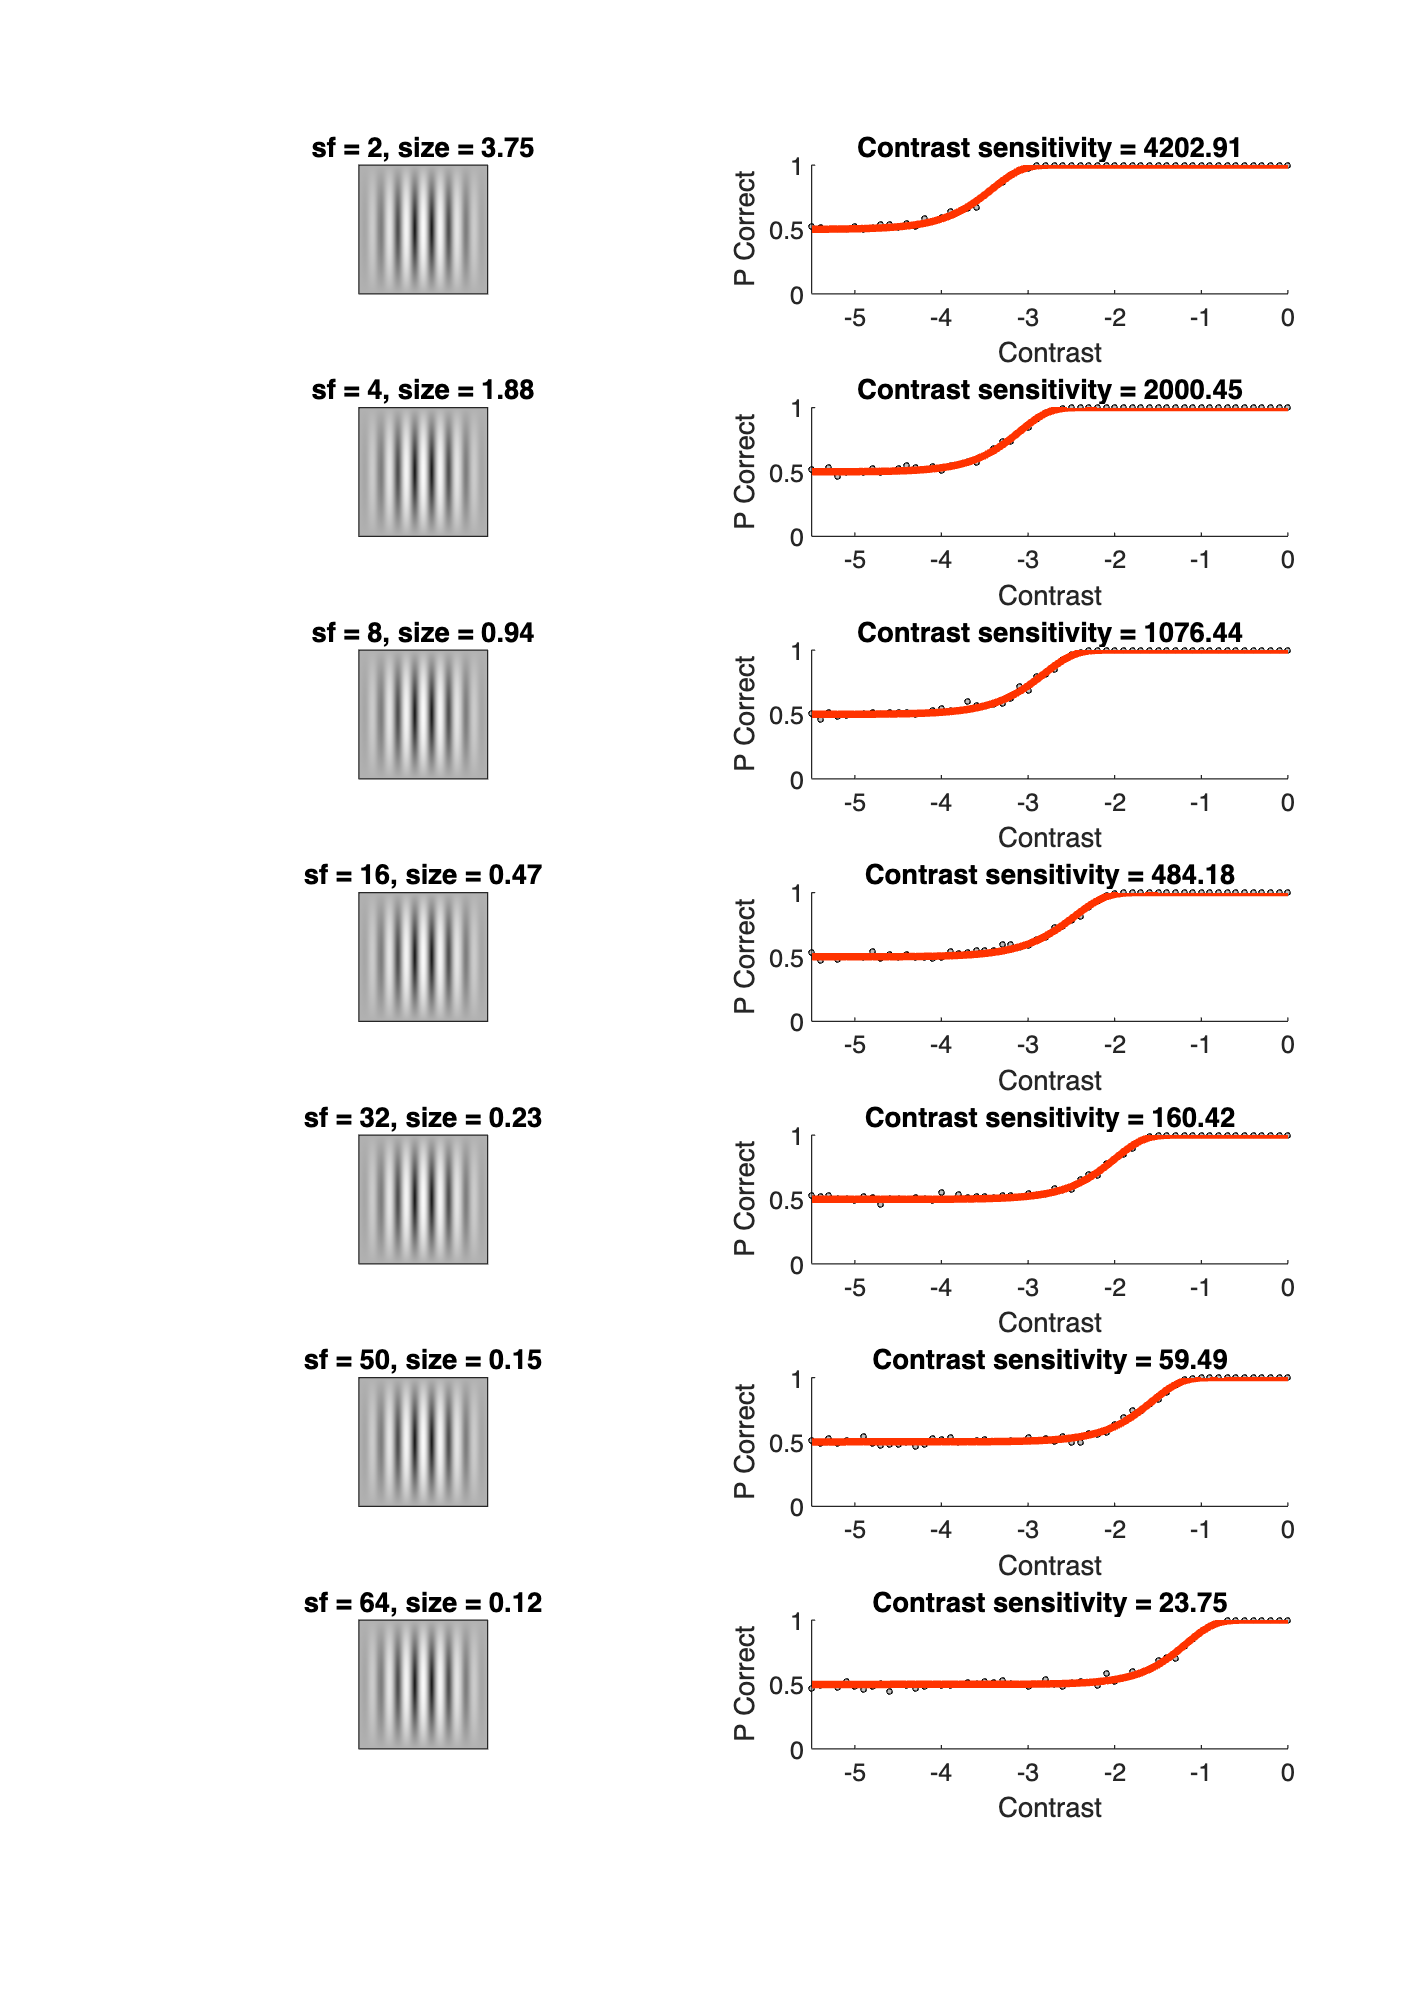

visualizationContrast = 1.0;
figure
for f = 1:numFreq
    subplot(numFreq,2,2*(f-1)+1)
    % Compute the scene sequence
    theSceneSequence = theSceneEngine{f}.compute(visualizationContrast);
    theSceneEngine{f}.visualizeStaticFrame(theSceneSequence); axis square;
    title(sprintf('sf = %.d, size = %.2f', freq(f), S_width(f)));
    
    % Plot data and psychometric curve 
    subplot(numFreq,2,2*f)
    questObj{f}.plotMLE(2.5,'para', squeeze(PFparam(f,:)));
    title(sprintf('Contrast sensitivity = %.2f', sensitivity(f)));
end
set(gcf, 'Units','normalized', 'Position', [0,0,0.4,1]);

Plot the contrast sensitivity function given the ideal observer classifier

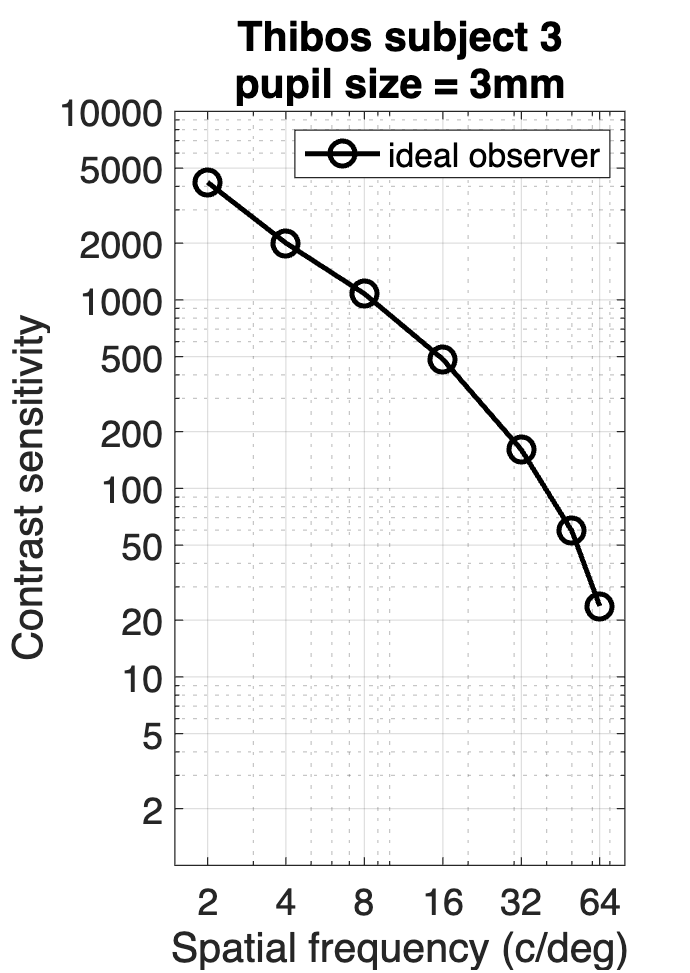

figure
loglog(freq, sensitivity, 'ko-','lineWidth',2, 'MarkerSize', 10); hold on
xlim([1.5, 80]); xticks(sort(2.^(1:6))); grid on
ylim([1, 1e4]); yticks([2,5,10,20,50,100,200,500,1e3, 2e3, 5e3, 1e4]);
xlabel('Spatial frequency (c/deg)'); ylabel('Contrast sensitivity');
title(sprintf('Thibos subject 3\npupil size = 3mm'));
legend('ideal observer');
set(gcf,'Units','normalized','Position',[0,0,0.12,0.3]);
set(gca,'FontSize',15);